%% =======================
% PART A: AUDIO & TEXT DATA
% =======================

clc;
clear;
close all;

%% -----------------------
% AUDIO DATA PARAMETERS
% -----------------------
fs_original = 44100;      % Sampling frequency (Hz)
bit_depth   = 16;         % Bits per sample
channels    = 1;          % Mono audio
duration_min = 10;        % Duration in minutes
duration_sec = duration_min * 60;

%% -----------------------
% RAW AUDIO STORAGE CALCULATION
% -----------------------
samples = fs_original * duration_sec;
audio_bits = samples * bit_depth * channels;
audio_bytes = audio_bits / 8;
audio_MB = audio_bytes / (1024^2);

fprintf('Raw Audio Storage (Uncompressed PCM):\n');

Raw Audio Storage (Uncompressed PCM):


fprintf('%.2f MB\n\n', audio_MB);

50.47 MB




%% -----------------------
% GENERATE DUMMY AUDIO SIGNAL
% -----------------------
t = 0:1/fs_original:5;            % 5-second signal for analysis
audio_signal = sin(2*pi*440*t);   % 440 Hz sine wave (A4 tone)

%% -----------------------
% DOWN-SAMPLING (LOSSY COMPRESSION DEMO)
% -----------------------
audio_down = decimate(audio_signal, 2);  % Down-sample by factor of 2
fs_down = fs_original / 2;

%% -----------------------
% STORAGE AFTER DOWN-SAMPLING
% -----------------------
samples_down = fs_down * duration_sec;
audio_bits_down = samples_down * bit_depth * channels;
audio_bytes_down = audio_bits_down / 8;
audio_MB_down = audio_bytes_down / (1024^2);

fprintf('Down-sampled Audio Storage:\n');

Down-sampled Audio Storage:


fprintf('%.2f MB\n\n', audio_MB_down);

25.23 MB




%% -----------------------
% COMPRESSION RATIO
% -----------------------
compression_ratio_audio = audio_MB / audio_MB_down;
fprintf('Audio Compression Ratio: %.2f : 1\n\n', compression_ratio_audio);

Audio Compression Ratio: 2.00 : 1



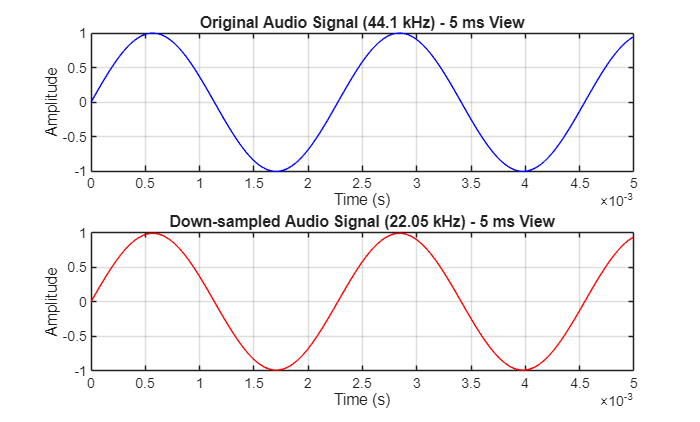


%% -----------------------
% PLOT AUDIO SIGNALS (ZOOMED VIEW)
% -----------------------
% Plot only first 5 milliseconds for clear visualization
time_window = 0.005;   % 5 ms

idx_orig = t <= time_window;
t_down = (0:length(audio_down)-1) / fs_down;
idx_down = t_down <= time_window;

figure;
subplot(2,1,1);
plot(t(idx_orig), audio_signal(idx_orig), 'b');
title('Original Audio Signal (44.1 kHz) - 5 ms View');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(2,1,2);
plot(t_down(idx_down), audio_down(idx_down), 'r');
title('Down-sampled Audio Signal (22.05 kHz) - 5 ms View');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;


%% =======================
% TEXT DATA STORAGE
% =======================

pages = 15;
chars_per_page = 1800;       % Assumed characters per page
text_bytes = pages * chars_per_page;   % ASCII text (1 byte/char)
text_KB = text_bytes / 1024;

fprintf('Text Storage Requirement:\n');

Text Storage Requirement:


fprintf('%.2f KB\n', text_KB);

26.37 KB
